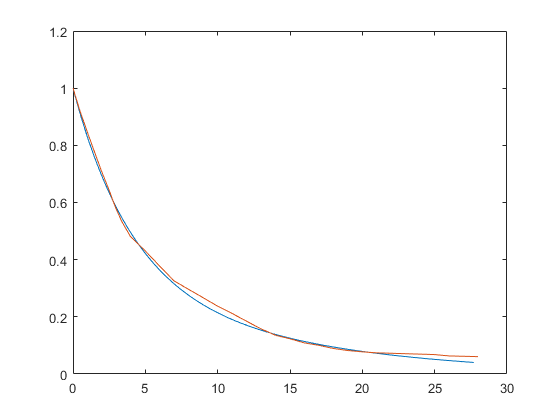

clc
clear 
close all

global Ta Mf Mi

load("M_exp50.mat",'unnamed')

t=0:0.1*3600:27.7*3600;

Ta=50;

W0=10; % "Peso inicial del producto [kg]"
m_i=0.872; % "Contenido inicial de humedad del producto en base húmeda"
Mi=m_i/(1-m_i); % "Contenido inicial de humedad del producto en base seca"

mwi=W0*m_i; % "Contenido inicial de masa de agua"
md=mwi/Mi; % "masa de producto seco [kg]"
m_f=0.05; % "Contenido final de humedad en base húmeda"


Mf=m_f/(1-m_f); % "Contenido final de humedad en base seca"

mwf=Mf*md; % "Masa final de agua [kg]"

M(1)=Mi;

x0=M(1); % Valores iniciales
[~,x]=ode23tb(@fun_2terms,t,x0); %Resolución de ecuaciones diferenciales.
MR=(x-Mf)/(Mi-Mf);
plot(t/3600,MR,unnamed(:,1)/60,unnamed(:,2))

function fx=fun_2terms(t,x)

global Ta Mf Mi

M=x;

a = 0.001549802296*Ta^2 - 0.194270355459*Ta + 6.179398377942;
b = -0.001633299645*Ta^2 + 0.205209969737*Ta - 5.511302504256;
k0 = (0.000000114872*Ta^2 - 0.000013960429*Ta + 0.000430526990);
k1 = (0.000000136537*Ta^2 - 0.000015212285*Ta + 0.000488869061);

% a = (0.002626891293*Ta^2 - 0.339796621501*Ta + 11.088495373748);
% b = (-0.002760551940*Ta^2 + 0.356755858371*Ta - 10.595972540563);
% k0 = (0.000018365952*Ta^2 - 0.002364205941*Ta + 0.076471525774)/60;
% k1 = (-0.000009672186*Ta^2 + 0.001380718313*Ta - 0.043674142663)/60;

%k=(0.000002536051*Ta^2 - 0.000219457213*Ta + 0.007758062225)/60;

%MR=a*exp(-k0*t)+b*exp(-k1*t);

%MR=exp(-k*t);
%fx=-k*(M-Mf);
fx = - (a * k0 * exp(-k0 * t) + b * k1 * exp(-k1 * t)) * (Mi -Mf);

end
%plot(t/3600,MR,unnamed(:,1)/60,unnamed(:,2))